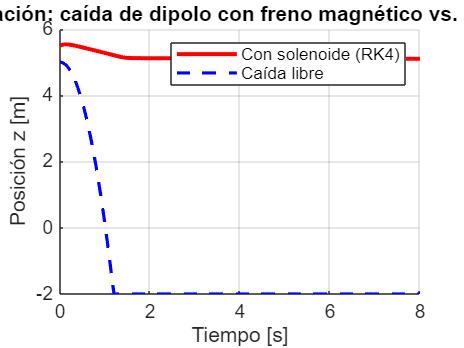

% main.m (fragmento)
[t, zm] = simular_frenado_test(Bz_total, malla_z);

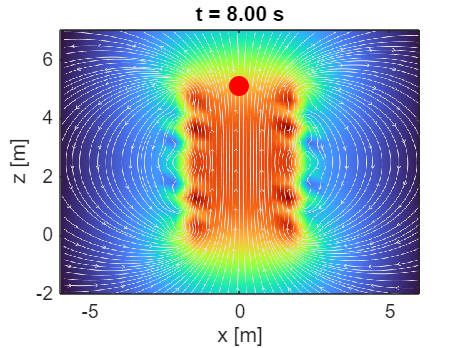


% Configura el video
writerObj = VideoWriter('caida_imán.mp4', 'MPEG-4');
writerObj.FrameRate = 20;
open(writerObj);

% Prepara la figura y el fondo (si tienes imagen)
figura = figure;
img = imread('solenoide.png');
x_range = [-6, 6];
z_range = [min(malla_z), max(zm)+1.5];

for k = 1:length(t)
  cla(figura);
  imagesc(x_range, z_range, flipud(img));  % fondo si lo quieres
  axis xy; hold on;
  % dibuja el imán en (x=0, z=zm(k))
  scatter(0, zm(k), 100, 'r', 'filled');
  xlabel('x [m]'); ylabel('z [m]');
  title(sprintf('t = %.2f s', t(k)));
  drawnow;

  frame = getframe(figura);
  writeVideo(writerObj, frame);
end


close(writerObj);
disp('¡Video generado: caida_imán.mp4!');

¡Video generado: caida_imán.mp4!
